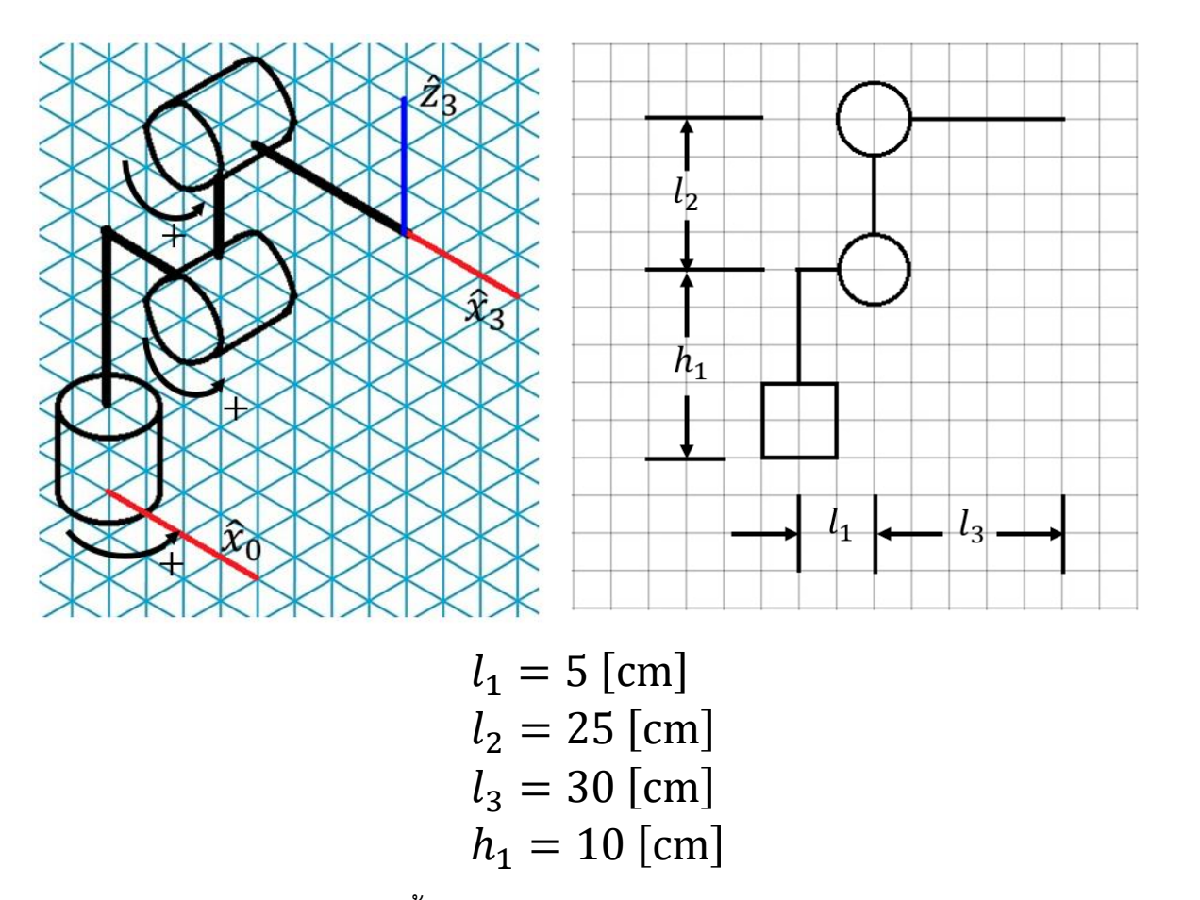                                                                                                                                                                                                                                

**input**

    .txt:    robot command = (2,n)

    .txt:    via_point_info = (3,m) // m = size of command via_points_task set in task space

**local variable**

    command = (1,n) L:0,J:1 

    via_point_task = (3,n) 

    via_point_joint_all = (3,n,4)

    via_point_joint = (3,n)

**step(function)**

readVariable => task2jointConversion =>  select optimal joint => gen C

**readVariable:** write .txt + return: via_point_task = (3,n), command = (1,n) L:0,J:1 

      Description: read variable

**task2jointConversion:** third dimension = all possible via point in joint space + return alert 0: cant access, 1: accessable; via_point_joint

      Description: check possible access + convert task to joint

% data1 = importdata('robot_command_v0.txt')
% data1 = data1{1}
% via_point_task = [ 0.35,  0.596202,    0.262132,    -0.162132;
%                       0,         0,           0,           0;
%                    0.35,  0.143412,    0.562132,    0.562132];
via_point_task = [0.35;0;0.35];
[alert, via_point_joint] = task2jointConversion(via_point_task);
% [q,flag] = inverseKine(via_point_task)
siz = size(via_point_joint);
for i=1:siz(3)
    p = forwardKine(via_point_joint(:,:,i))
%     via_point_joint(:,:,i)
    i
end

p =     0.3500
         0
    0.3500


i = 1

p =     0.3500
         0
    0.3500


i = 2

p =     0.3500
   -0.0000
    0.3500


i = 3

p =     0.3500
   -0.0000
    0.3500


i = 4